# Modelling of Particle with mass m with an external force acting on it.

## Clear all data

clc;
clear all;
close all;
clf; %Clear all figures

## Basic Definition

particle_mass = 1; % mass of particle in kg
initial_parameters = [0 ; 0; 10; 0]; % Initial (x,x_dot,y,y_dot) parameters of particle
applied_force = [9.8 * sqrt(2) ; 45]; % Applied force to the particle (F, thetha) 
% where F is the magnitude and thetha is the angle of application of force wrt to +ve x axis
gravitational_acceleration = 9.8; %m/s2
graph_time = 10; % Time frame for plotting

## Symbolic Definition

syms t theta(t) v x(t) y(t) F h m g 'real' % Creating Symbolic Variables

sympref('AbbreviateOutput',false);
sympref('MatrixWithSquareBrackets',true);
sympref('PolynomialDisplayStyle','ascend');

## Define Generalised Coordinates

q = sym('q',[2,1]);
q(1) = x;
q(2) = y;
q

$$q = \left[\begin{array}{c} x\left(t\right)\\ y\left(t\right) \end{array}\right]$$

dq = diff(q,t)

$$dq = \left[\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right) \end{array}\right]$$

$$dq = \left[\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right) \end{array}\right]$$

## Defining Generalised Inputs

u = sym('u',[2,1]);
u(1) = F*cos(theta);
u(2) = F*sin(theta);
u

$$u = \left[\begin{array}{c} F\,\cos\left(\theta \left(t\right)\right)\\ F\,\sin\left(\theta \left(t\right)\right) \end{array}\right]$$

## Derive Lagrangian Function

PE = m*g*h;
PE = subs(PE,h,y)

$$PE = g\,m\,y\left(t\right)$$

KE = (m*(v^2)/2);
KE = subs(KE,[v],[sqrt(diff(x,t)^2 + diff(y,t)^2)])

$$KE = \frac{m\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\right)}{2}$$

LE = KE - PE

$$LE = \frac{m\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\right)}{2}-g\,m\,y\left(t\right)$$

## Derive Euler Lagrangian Equations

dLE_dq = jacobian(LE,q)

$$dLE\_dq = \left[\begin{array}{cc} 0 & -g\,m \end{array}\right]$$

dLE_ddq = jacobian(KE,dq)

$$dLE\_ddq = \left[\begin{array}{cc} m\,\frac{\partial }{\partial t}x\left(t\right) & m\,\frac{\partial }{\partial t}y\left(t\right) \end{array}\right]$$

d_dLE_dtDdq = diff(dLE_ddq,t)

$$d\_dLE\_dtDdq = \left[\begin{array}{cc} m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right) & m\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right) \end{array}\right]$$

EU_eq1 = d_dLE_dtDdq(1,1) - dLE_dq(1,1) - u(1,1)

$$EU\_eq1 = m\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-F\,\cos\left(\theta \left(t\right)\right)$$

EU_eq2 = d_dLE_dtDdq(1,2) - dLE_dq(1,2) - u(2,1)

$$EU\_eq2 = m\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-F\,\sin\left(\theta \left(t\right)\right)+g\,m$$

syms theta x_dot x_ddot y_dot y_ddot 'real';
EU_eq1 = subs(EU_eq1,[x, diff(x,t),diff(x,t,2),y, diff(y,t),diff(y,t,2)],[x, x_dot, x_ddot,y, y_dot, y_ddot])

$$EU\_eq1 = -\cos\left(\theta \left(t\right)\right)\,F+m\,\ddot{x}$$

EU_eq2 = subs(EU_eq2,[x, diff(x,t),diff(x,t,2),y, diff(y,t),diff(y,t,2)],[x, x_dot, x_ddot,y, y_dot, y_ddot])

$$EU\_eq2 = -\sin\left(\theta \left(t\right)\right)\,F+g\,m+m\,\ddot{y}$$

## Defining State Space Matrix

X = sym('X',[4,1]); %Create a 4X1 State Space Matrix Vector
X(1) = x;
X(2) = x_dot;
X(3) = y;
X(4) = y_dot;
X

$$X = \left[\begin{array}{c} x\left(t\right)\\ \dot{x}\\ y\left(t\right)\\ \dot{y} \end{array}\right]$$

## Symbolic Solution to form state space matrix

[x_ddot, y_ddot] = solve([EU_eq1,EU_eq2],[x_ddot,y_ddot]);

## Calculating dX Matrix

dX = sym('dX',[4,1]); %Create a 4x1 dX Matrix
dX(1) = X(2,1);
dX(2) = x_ddot;
dX(3) = X(4,1);
dX(4) = y_ddot;
dX

$$dX = \left[\begin{array}{c} \dot{x}\\ \frac{F\,\cos\left(\theta \left(t\right)\right)}{m}\\ \dot{y}\\ \frac{\sin\left(\theta \left(t\right)\right)\,F-g\,m}{m} \end{array}\right]$$

## Substituting values fed by user

sub_dX = subs( ...
    dX, ...
    [F,theta,m,g], ...
    [applied_force(1,1),applied_force(2,1),particle_mass,gravitational_acceleration])

$$sub\_dX = \left[\begin{array}{c} \dot{x}\\ \frac{49\,\sqrt{2}\,\cos\left(45\right)}{5}\\ \dot{y}\\ \frac{49\,\sqrt{2}\,\sin\left(45\right)}{5}-\frac{49}{5} \end{array}\right]$$

%Substitue Values
fun_dX = @(t,x)[
    x(2);
    double(sub_dX(2,1));
    x(4);
    double(sub_dX(4,1))];
% Convert the symbolic matrix to double matrix 

## Calculating Differential Equation to get velocity

tspan = [0: 0.1: graph_time];
rsize = size(tspan);
[t,x] = ode45(fun_dX,tspan,initial_parameters);

## Plotting Graphs

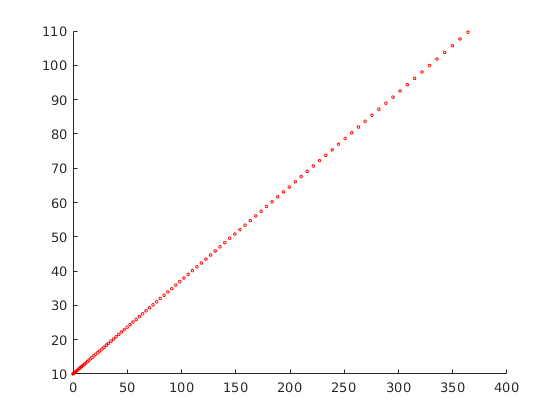

for i = 1:1:rsize(1,2)
    %plot(xunit, yunit,'k','LineStyle','--'); % Draw Circular Axes
    hold on;
    plot(x(i,1), x(i,3), 'ro','MarkerSize',2);
    pause(0.1); % pause to see realtime animation. Given in seconds
    hold off;
end